# Women's 200m Backstroke

Instructions are in the task pane to the left. Complete and submit each task one at a time.

## Task 1

backstroke = readtable("./data/backstroke.csv");
country = backstroke.country;
name = backstroke.name;
time = [backstroke.time_1 backstroke.time_2 backstroke.time_3 backstroke.time_4];

## Task 2

The file `backstroke.mat` contains times for each swimmer from the 2016 Olympic women's backstroke finals. It contains the following three variables.

- `time` is a matrix containing the times of the eight swimmers (rows) at 50, 100, 150, and 200 meters (columns)

- `name` is a cell array containing the swimmers' last names

- `country` is a cell array containing each swimmer's national code

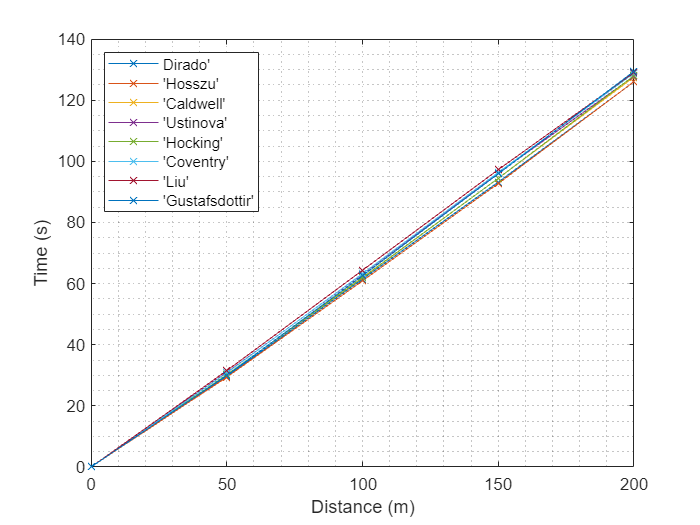

time = [zeros(8, 1) time];
d = 0:50:200;
plot(d, time, "x-")
grid minor
xlabel("Distance (m)")
ylabel("Time (s)")
xticks(d)
legend(name, "Location", "northwest")

## Task 3

Because all the athletes are so closely matched, it's difficult to see what's happening in this plot.

Instead you can see how each swimmer's time compares to the fastest at each distance.

plot(d,(time - min(time)), "x-")
grid minor
xlabel("Distance (m)")
ylabel("Time Behind Lead (s)")
xticks(d)
legend(country, "Location", "eastoutside")

## Task 4

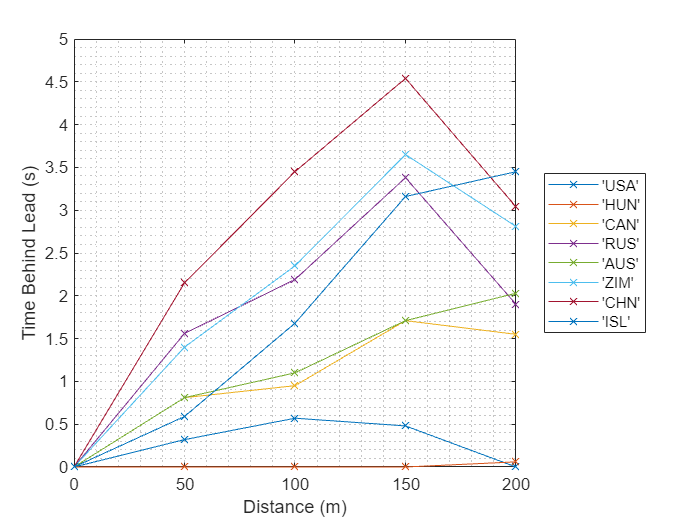

plot(diff(time, [], 2)', "x-")
grid minor

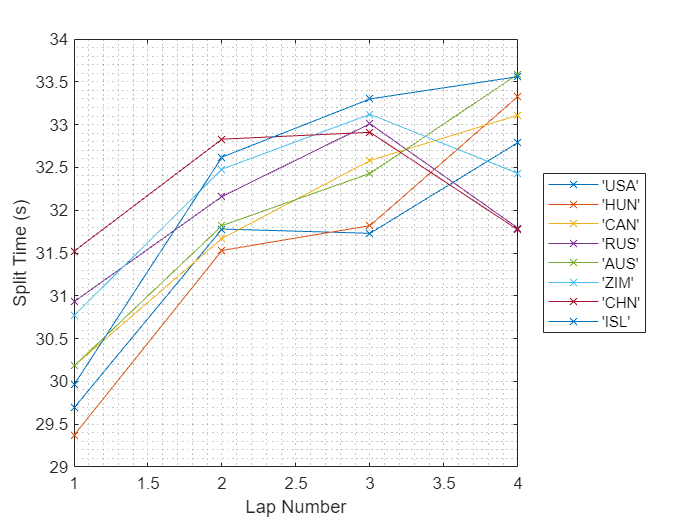

xlabel("Lap Number")
xlim([1 4])
ylabel("Split Time (s)")
legend(country, "Location", "eastoutside")